# Tutorial of the Unbiased Competition Model

This tutorial demonstrates how to implement the Unbiased Competition Model presented in [Ardid, Sherfey et al. 2019](https://doi.org/10.1073/pnas.1812535116).

- **Goals**: 

- Illustrate the creation and usage of DynaSim models endowed with mechanisms specified by the user. 

- Show how to modify the oscillatory dynamics of the model by tuning the parameters of its inputs.

- **Structure**: After a brief introduction, the first part of the tutorial shows how to load DynaSim and set up the asynchronous (non-oscillatory) version of the model. The execution of the model is done in section Run the simulation.  Visualization of the results is explained in section Visualize the results. The second part of the tutorial shows how to incorporate the oscillatory component into the model, run the simulation and visualize the results.

- **Reference:**

- Ardid S, Sherfey JS, McCarthy MM, Hass J, Pittman-Polletta BR, Kopell N. Biased competition in the absence of input bias revealed through corticostriatal computation. Proc Natl Acad Sci U S A. 2019;116(17):8564-8569. doi:10.1073/pnas.1812535116

## Background

We conceptualize Unbiased Competition as biased competition in the absence of input bias, in contraposition to the traditional Biased Competition conception, which refers to biased competition due to an external input bias.

## Load DynaSim

If you haven't loaded DynaSim, do it.

DynaSim_path = '../../..';
addpath(genpath(DynaSim_path));

## 1. Implementation

In this section, we specify the initial settings both of the simulation (how and for how long we integrate the model) and that of the model itself (all its mechanisms and their parameters).

### Simulation parameters

Here, we specify the integration parameters: the integration time step (dt), the solver that we will be using (e.g., rk4), the duration of the simulation, an initial onset time (different than 0, if wanted), and the transient time (which is used to ensure that dynamics is not affected by initial conditions).

%% Simulation time definition (in ms)
dt = 0.05           % Integration time step

dt = 0.0500

solver =  'rk4'      % Integration solver

solver = 'rk4'

duration = 1500     % Simulation duration

duration = 1500

tOn = 0;                           % Initial time onset
tspan = [tOn,tOn+duration];        % Simulation interval
transient = 500    % Transient time

transient = 500

### Model specification

We start defining the ordinary differential equations (ODEs) we want to simulate. Later on, we will embed these equations into the model specification, which we define in Section Population specification. In this case we integrate each cell's voltage (state variable V) according to its input currents. For this, we use a DynaSim linker (@current) that will be internally replaced by the sum of all the input terms. We also need to define the initial conditions of the state variable (V), i.e., its initial value. Finally, we use a DynaSim monitor to tell DynaSim to save the data of the total current (@current) at each time step.

eqns = {
         'dV/dt = @current'             % Ordinary Differential Equation (ODE)
         'V(0) = -70+10*randn(1,Npop)'  % Initial Conditions (IC)
         'monitor @current'             % Monitor of the total current through the @current Linker
       }

eqns = 3×1 cell array
    {'dV/dt = @current'           }
    {'V(0) = -70+10*randn(1,Npop)'}
    {'monitor @current'           }


### Cell multiplicity

Our model consists of two types of striatal cells: D1 and D2 Spiny Projecting Neurons, D1 and D2 SPNs for short.

nSPNs = 150;     % Number of individual SPN cells
multiplicity = [nSPNs,nSPNs]     % Total number of SPN cells of each type [D1 SNPs, D2 SPNs] in the model

multiplicity =    150   150


### Parameters of intrinsic currents

Section Population specification sets the list of mechanisms each cell type possesses. These mechanisms are fully specified in separate files. DynaSim users can access a repertoire of mechanisms in DynaSim's library, but sometimes we need to create our own. In such a case, the path to the mechanisms needs to be 'visible', either because is local to the live script (same folder), or because the mechanisms folders have been previously added to the path. Most of the parameters of the mechanisms have been set in their respective files (we encourage the reader to open and inspect those files). Here we will override only those parameters that take different values in D1 and D2 SPNs.

% Leak current parameters
g_l_D1 = 0.096      % mS/cm^2, Leak conductance for D1 SPNs 

g_l_D1 = 0.0960

g_l_D2 = 0.1        % mS/cm^2, Leak conductance for D2 SPNs

g_l_D2 = 0.1000


% Ca current parameters
g_cat_D1 = 0.018    % mS/cm^2, Conductance of the T-type Ca2+ current for D1 SPNs

g_cat_D1 = 0.0180

g_cat_D2 = 0.025    % mS/cm^2, Conductance of the T-type Ca2+ current for D2 SPNs

g_cat_D2 = 0.0250

### Parameters of external Poisson synaptic inputs from PFC

Now, we override the values of the external Poisson inputs from PFC. We start specifying the interval in which these inputs are applied. Next, we set up the rate of the non-oscillatory component, and consider 3 different conditions: input of high strength, input of low strength, and no input (spontaneous activity). In this section, we consider non-oscillatory inputs only. For oscillatory inputs, see How to change the dynamics of the model.

% Interval of the PFC input
tOn_pfcInp = transient            % onset in ms

tOn_pfcInp = 500

tOff_pfcInp = tOn+duration        % offset in ms

tOff_pfcInp = 1500


% Rate of reference for the non-oscillatory (DC) component, i.e. asynchronous input
DC_ref = 44e3                     % in spks/s

DC_ref = 44000


% Three cases: High strength async input, Low strength async input and no input (spontaneous activity)
pfcInp_DC_ref = DC_ref            % high input

pfcInp_DC_ref = 44000

pfcInp_DC_red = DC_ref/5          % low input

pfcInp_DC_red = 8800

pfcInp_DC_spont = 0               % no input

pfcInp_DC_spont = 0

### Parameters of recurrent synaptic connections

Similarly, we override parameters of the recurrent GABA connections among SPNs that are specific of each type of connection: the probability of connection, the maximum conductance, the synaptic time constants, as well as the time constant of short-term depression.

% Connection probabilities
conn_prob_gaba_D1toD1 = 0.26               % D1->D1 prob. of connection

conn_prob_gaba_D1toD1 = 0.2600

conn_prob_gaba_D1toD2 = 0.06               % D1->D2 prob. of connection

conn_prob_gaba_D1toD2 = 0.0600

conn_prob_gaba_D2toD1 = 0.27               % D2->D1 prob. of connection

conn_prob_gaba_D2toD1 = 0.2700

conn_prob_gaba_D2toD2 = 0.36               % D2->D2 prob. of connection

conn_prob_gaba_D2toD2 = 0.3600


% GABA maximum conductances
g_gaba_D1 = 0.65/multiplicity(1)           % mS/cm^2, maximum conductance per cell

g_gaba_D1 = 0.0043

g_gaba_D2 = 0.4125/multiplicity(2)         % mS/cm^2, maximum conductance per cell

g_gaba_D2 = 0.0028

cross_inhibition_factor = 1.5              % multiplicative factor for cross-inhibition connections (D1->D2 and D2->D1)

cross_inhibition_factor = 1.5000


% GABA time constant for each connection
median_tau_gaba = 30.4;                    % ms
sig_tau_gaba = 8.2;                        % ms
tau_gaba_D1 = median_tau_gaba + sig_tau_gaba*randn(1,multiplicity(1));
tau_gaba_D2 = median_tau_gaba + sig_tau_gaba*randn(1,multiplicity(2));

% Time constant of short-term depression
tauD_D1 = 1030;                            % ms
tauD_D2 = 210;                             % ms

### Population specification

Here we specify the details of the two populations in the model, D1 and D2 SPNs: number of neurons, main equations, list of mechanisms embedded in each neuron's model and parameters that should be overriden from default values:

s = []; % Create an empty structure to write DynaSim's model full specification

% D1 SPN population specification
s.populations(1).name = 'D1_SPN';
s.populations(1).size = multiplicity(1);
s.populations(1).equations = eqns;
s.populations(1).mechanism_list = {'spn_iNa','spn_iK','spn_iLeak','spn_iM','spn_iCa','spn_CaBuffer','spn_iKca','spn_iPoisson','spn_ipfcPoisson'};
s.populations(1).parameters = {'cm',1,'g_l',g_l_D1,'g_cat',g_cat_D1,'onset_pfc_poisson',tOn_pfcInp,'offset_pfc_poisson',tOff_pfcInp};

% D2 SPN population specification
s.populations(2).name = 'D2_SPN';
s.populations(2).size = multiplicity(2);
s.populations(2).equations = eqns;
s.populations(2).mechanism_list = {'spn_iNa','spn_iK','spn_iLeak','spn_iM','spn_iCa','spn_CaBuffer','spn_iKca','spn_iPoisson','spn_ipfcPoisson'};
s.populations(2).parameters = {'cm',1,'g_l',g_l_D2,'g_cat',g_cat_D2,'onset_pfc_poisson',tOn_pfcInp,'offset_pfc_poisson',tOff_pfcInp};

### Connections specification

Next, we move into the recurrent synaptic connections among the populations and specify their properties: the specific synaptic mechanism used, and how its internal parameters are tweaked according to each type of connection: connection probability, maximum conductance and time constants (synaptic and short-time depression):

% D1->D1 connection specification
s.connections(1).direction = 'D1_SPN->D1_SPN';
s.connections(1).mechanism_list = {'spn_iGABA'};
s.connections(1).parameters = {'conn_prob_gaba',conn_prob_gaba_D1toD1,'g_gaba',g_gaba_D1,'tau_gaba',tau_gaba_D1,'tauD_gaba',tauD_D1};

% D1->D2 connection specification
s.connections(2).direction = 'D1_SPN->D2_SPN';
s.connections(2).mechanism_list = {'spn_iGABA'};
s.connections(2).parameters = {'conn_prob_gaba',conn_prob_gaba_D1toD2,'g_gaba',cross_inhibition_factor*g_gaba_D1,'tau_gaba',tau_gaba_D1,'tauD_gaba',tauD_D1};

% D2->D1 connection specification
s.connections(3).direction = 'D2_SPN->D1_SPN';
s.connections(3).mechanism_list = {'spn_iGABA'};
s.connections(3).parameters = {'conn_prob_gaba',conn_prob_gaba_D2toD1,'g_gaba',cross_inhibition_factor*g_gaba_D2,'tau_gaba',tau_gaba_D2,'tauD_gaba',tauD_D2};

% D2->D2 connection specification
s.connections(4).direction = 'D2_SPN->D2_SPN';
s.connections(4).mechanism_list = {'spn_iGABA'};
s.connections(4).parameters = {'conn_prob_gaba',conn_prob_gaba_D2toD2,'g_gaba',g_gaba_D2,'tau_gaba',tau_gaba_D2,'tauD_gaba',tauD_D2};

### Run the simulation

Once the model is properly specified, we proceed to run the simulation according to the simulation parameters, population specification, and connections specification. For this we use the 'vary' argument in DynaSim, so we can run 3 related simulations in 1 call. Specifically, we vary the strength of the asynchronous input coming from PFC, as explained above.

% Simulate pfc DC input variation
pfcInp_DC = [pfcInp_DC_spont, pfcInp_DC_red, pfcInp_DC_ref];
pfcInp_DCcond_labels = {'Spontaneous', 'Low Async Input', 'High Async Input'};
vary_DCcond = {
                '(D1_SPN,D2_SPN)','DC_pfc_poisson',pfcInp_DC
              };
data_DCcond = dsSimulate(s,'time_limits',tspan,'vary',vary_DCcond,'dt',dt,'solver',solver);

### Visualize the results

Finally, we display the raster plots and instantaneous firing rates of the two populations (D1 SPNs in blue, and D2 SPNs in red), as well as individual voltage traces from those simulations as follows:

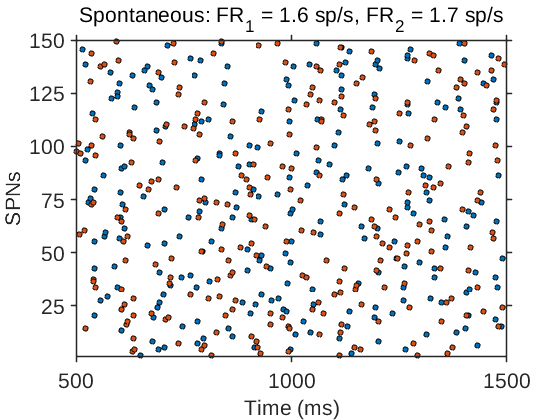

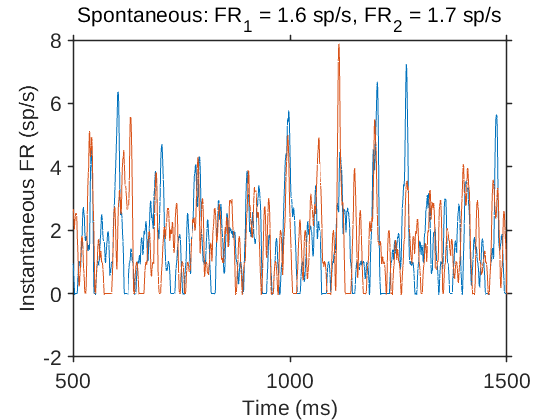

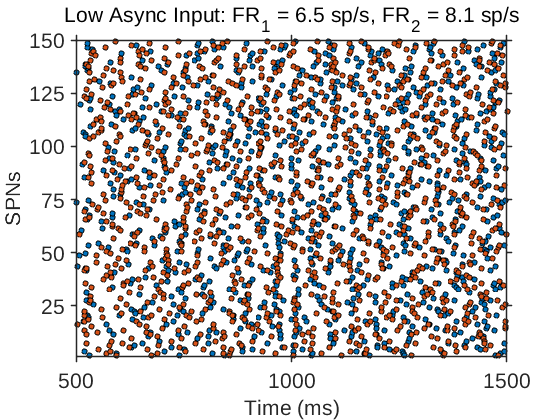

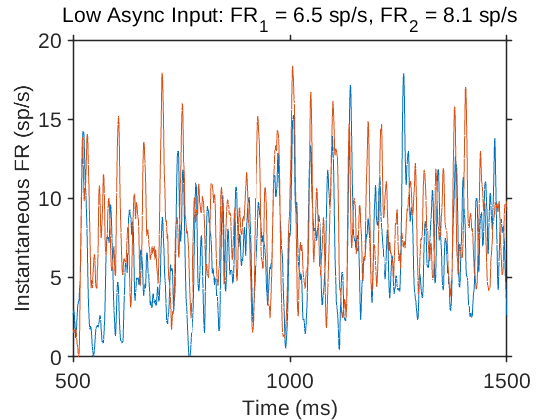

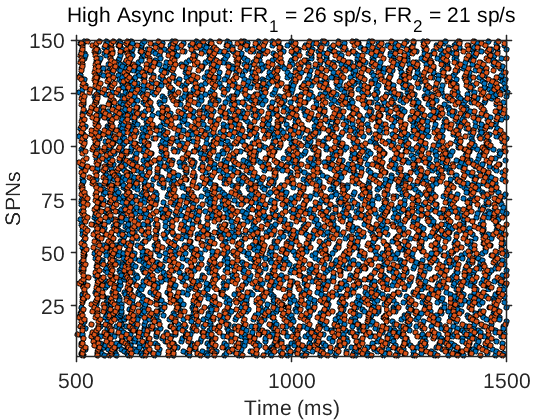

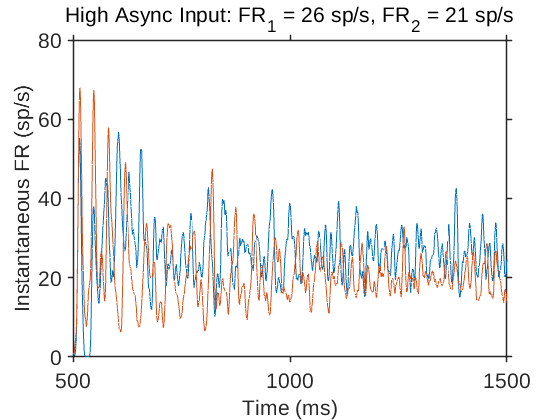

fontSize = 16;
lineWidth = 1;

% Raster plots (Fig. 3A) and instantaneous firing rates (as in Fig 3B and Fig. 4)

kwidth      = 5;  % width of kernel regression in ms
Ts          = 1;  % subsampling period in ms
pool        = []; % all neurons (or specify which ones)
flag_interp = 1;  % whether to interpolate to keep the original sampling frequency

if flag_interp
    instFR_D1 = nan(numel(pfcInp_DC), ceil(duration/dt) + 1);
    instFR_D2 = nan(numel(pfcInp_DC), ceil(duration/dt) + 1);
else
    instFR_D1 = nan(numel(pfcInp_DC), ceil(duration/Ts) + 1);
    instFR_D2 = nan(numel(pfcInp_DC), ceil(duration/Ts) + 1);
end

for iSim = 1:numel(pfcInp_DC)
    raster{1} = computeRaster(data_DCcond(iSim).time,data_DCcond(iSim).D1_SPN_V);
    raster{2} = computeRaster(data_DCcond(iSim).time,data_DCcond(iSim).D2_SPN_V);
    tl = tOn + [transient, duration];
    rate = plotRaster(multiplicity,tl,raster);
    prev_title = get(gca,'title');
    title([pfcInp_DCcond_labels{iSim} ': ' prev_title.String])

    instFR_D1(iSim,:) = 1e3*NWepanechnikovKernelRegrRaster(data_DCcond(iSim).time,raster{1},pool,kwidth,Ts,flag_interp);
    instFR_D2(iSim,:) = 1e3*NWepanechnikovKernelRegrRaster(data_DCcond(iSim).time,raster{2},pool,kwidth,Ts,flag_interp);
    
    figure
    plot(data_DCcond(iSim).time,instFR_D1(iSim,:),data_DCcond(iSim).time,instFR_D2(iSim,:),'LineWidth',lineWidth)
    set(gca,'fontSize',fontSize,'LineWidth',lineWidth,'TickDir','out','Box','on')
    xlim(tl)
    xlabel('Time (ms)','fontSize',fontSize)
    ylabel('Instantaneous FR (sp/s)','fontSize',fontSize)
    title(prev_title.String,'fontSize',fontSize,'FontWeight','Normal')
    drawnow
end

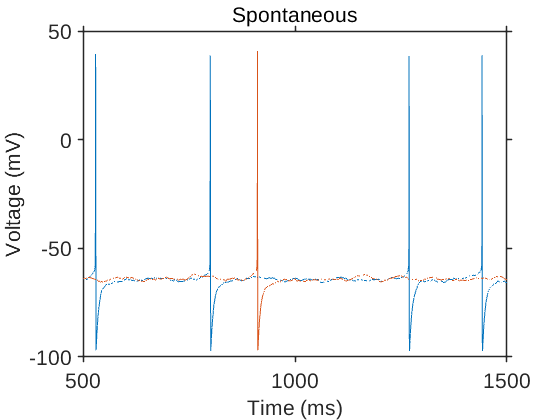

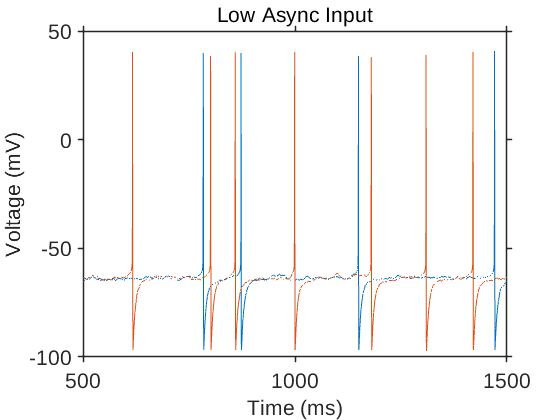

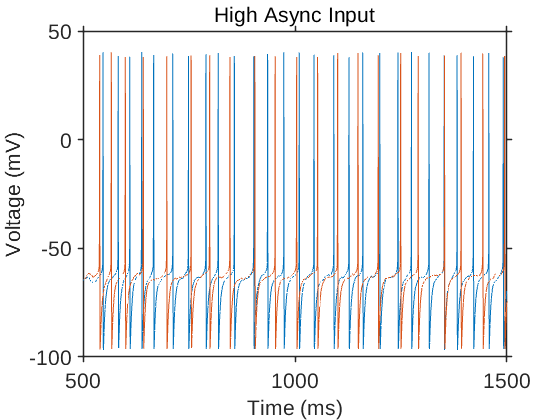


% Single-cell voltage traces (randomly picked)

for iSim = 1:numel(pfcInp_DC)
    figure
    plot(data_DCcond(iSim).time,data_DCcond(iSim).D1_SPN_V(:,randi(multiplicity(1))),data_DCcond(iSim).time,data_DCcond(iSim).D2_SPN_V(:,randi(multiplicity(2))),'LineWidth',lineWidth)
    set(gca,'fontSize',fontSize,'LineWidth',lineWidth,'TickDir','out','Box','on')
    xlim(tl)
    xlabel('Time (ms)','fontSize',fontSize)
    ylabel('Voltage (mV)','fontSize',fontSize)
    title(pfcInp_DCcond_labels{iSim},'fontSize',fontSize,'FontWeight','Normal')
end

## 2. How to change the dynamics of the model

Here, we show how to activate the oscillatory component of the external Poisson inputs from PFC . You can use the slider below to change the dynamics of the model, and the drop-down menu to select one frequency band. Depending on the value of the frequency, we will focus in one of two different conditions: input of high strength, or input of low strength. Note that in the first part of the tutorial (the cases of non-oscillatory inputs), we used the 'vary' argument of DynaSim to run 3 different conditions in 1 call. Here, we are focusing in one simulation at a time, selected with the drop-down menu.

%% Parameters for the synchronous input
AC_ref = 7000; % in spks/s
pfcInp_AC_ref = AC_ref;               % high sync input
pfcInp_AC_red = AC_ref/5;             % low sync input

frequency =  18  

frequency = 18


if frequency ~= 18
  pfcInp_ACcond_label = 'High Sync Input'
  pfcInp_DC = pfcInp_DC_ref
  pfcInp_AC = pfcInp_AC_ref
else
  pfcInp_ACcond_label = 'Low Sync Input'
  pfcInp_DC = pfcInp_DC_red
  pfcInp_AC = pfcInp_AC_red
end

pfcInp_ACcond_label = 'Low Sync Input'

pfcInp_DC = 8800

pfcInp_AC = 1400


% Parameters of the duty cycle for the oscillatory component 
dutyPercentage_pfcInp = 50;
thresholdDUTY = cos(pi*dutyPercentage_pfcInp/100);

### Parameters

Here we adjust the parameters of the model to add the proper values for the synchronous (oscillatory) input from PFC:

%% Updating the population parameters from previous ones

s.populations(1).parameters = [s.populations(1).parameters(:)',{'f_pfc_poisson'},{frequency},{'DC_pfc_poisson'},{pfcInp_DC},{'AC_pfc_poisson'},{pfcInp_AC},{'thresholddutycycle_pfc_poisson'},{thresholdDUTY}];
s.populations(2).parameters = [s.populations(2).parameters(:)',{'f_pfc_poisson'},{frequency},{'DC_pfc_poisson'},{pfcInp_DC},{'AC_pfc_poisson'},{pfcInp_AC},{'thresholddutycycle_pfc_poisson'},{thresholdDUTY}];

### Run the simulation

With the model specified, we proceed to run the simulation.

%% Simulate the model

% Simulate pfc AC input variation
data_ACcond = dsSimulate(s,'time_limits',tspan,'dt',dt,'solver',solver);

### Visualize the results

Finally, we display the raster plots and instantaneous firing rates of the two populations (D1 SPNs in blue, and D2 SPNs in red), as well as individual voltage traces in the synchronous condition:

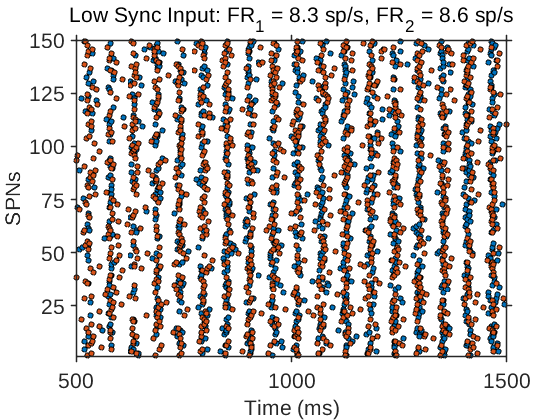

% Raster plots (Fig. 3A) and instantaneous firing rates (as in Fig 3B and Fig. 4)

raster{1} = computeRaster(data_ACcond.time,data_ACcond.D1_SPN_V);
raster{2} = computeRaster(data_ACcond.time,data_ACcond.D2_SPN_V);
tl = tOn + [transient, duration];
rate = plotRaster(multiplicity,tl,raster);
prev_title = get(gca,'title');
title([pfcInp_ACcond_label ': ' prev_title.String])

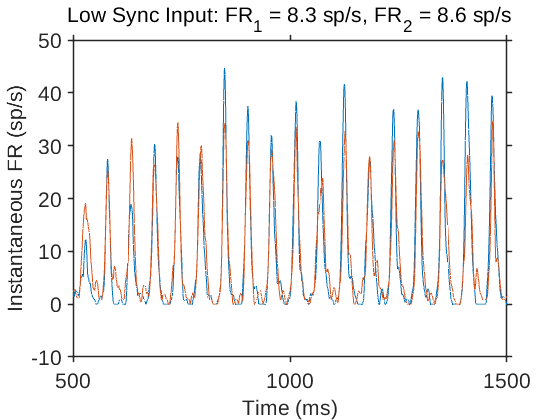


instFR_D1(iSim,:) = 1e3*NWepanechnikovKernelRegrRaster(data_ACcond.time,raster{1},pool,kwidth,Ts,flag_interp);
instFR_D2(iSim,:) = 1e3*NWepanechnikovKernelRegrRaster(data_ACcond.time,raster{2},pool,kwidth,Ts,flag_interp);
    
figure
plot(data_DCcond(iSim).time,instFR_D1(iSim,:),data_DCcond(iSim).time,instFR_D2(iSim,:),'LineWidth',lineWidth)
set(gca,'fontSize',fontSize,'LineWidth',lineWidth,'TickDir','out','Box','on')
xlim(tl)
xlabel('Time (ms)','fontSize',fontSize)
ylabel('Instantaneous FR (sp/s)','fontSize',fontSize)
title(prev_title.String,'fontSize',fontSize,'FontWeight','Normal')

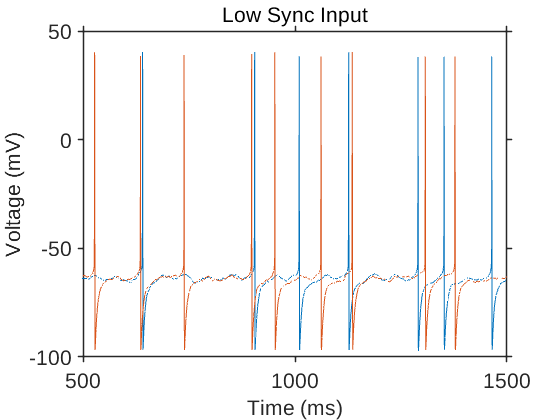

drawnow

% Single-cell voltage traces (randomly picked)

figure
plot(data_ACcond.time,data_ACcond.D1_SPN_V(:,randi(multiplicity(1))),data_ACcond.time,data_ACcond.D2_SPN_V(:,randi(multiplicity(2))),'LineWidth',lineWidth)
set(gca,'fontSize',fontSize,'LineWidth',lineWidth,'TickDir','out','Box','on')
xlim(tl)
xlabel('Time (ms)','fontSize',fontSize)
ylabel('Voltage (mV)','fontSize',fontSize)
title(pfcInp_ACcond_label,'fontSize',fontSize,'FontWeight','Normal')